### Load and Visualize Robot from Robot Library

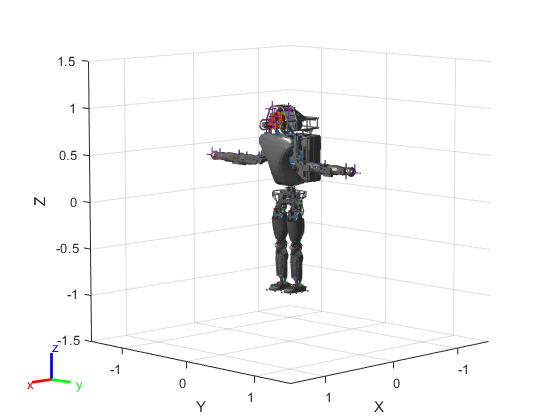

atlas = loadrobot("atlas", "DataFormat", "column");
figure; show(atlas, "FastUpdate", true, "PreservePlot", false);

### Zoom View Into Robot

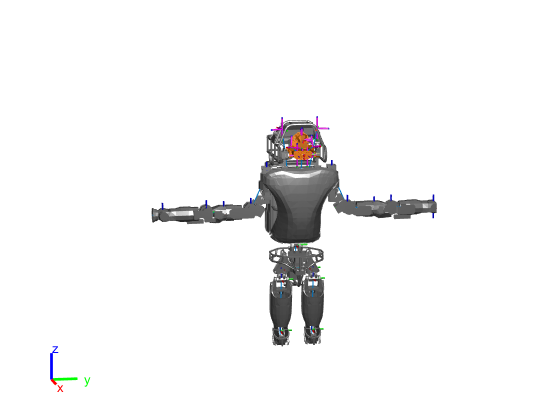

grid off
axis off

xlim([-1.05 0.91])
ylim([-1.01 0.95])
zlim([-0.53 1.43])
view([80.18 10.44])

### Interactively Adjust Robot Position

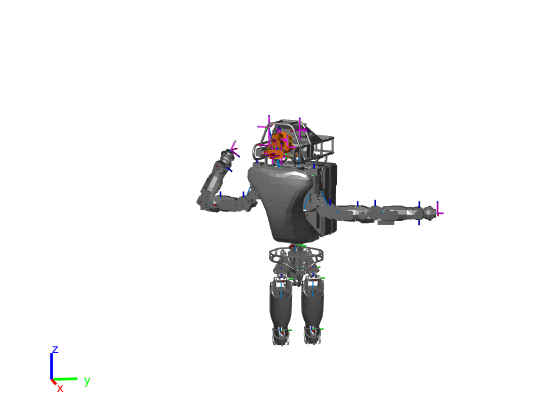

leftShoulder =30;
rightElbow =-120;
torsoRot = -40;

q = atlas.homeConfiguration;
q(1) = deg2rad(torsoRot);
q(4) = deg2rad(leftShoulder);
q(15) = deg2rad(rightElbow);
show(atlas, q, "FastUpdate", true, "PreservePlot", false);

### Calculate Smooth Joint Trajectory

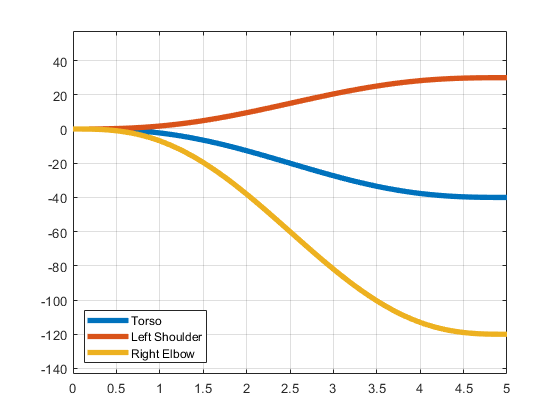

wpts = zeros(size(q,1), 2);
wpts([4,15,1],:) = [0.0 deg2rad(leftShoulder); 0.0 deg2rad(rightElbow); 0.0 deg2rad(torsoRot)];
 
% Define time vector
tvec = 0:0.01:5;
 
% Compute trajectory using default boundary conditions
qTraj = quinticpolytraj(wpts, [0 5], tvec);

figure

for t = 1:10:size(qTraj,2)
    plot(tvec(1:t), rad2deg(qTraj([1,4,15],1:t)), 'LineWidth', 4)
    grid on
    xlim([0,5]);
    ylim(rad2deg([-2.5,1]))
    legend(["Torso", "Left Shoulder", "Right Elbow"], "Location", "southwest")
    drawnow
end

### Visualize Robot Trajectory

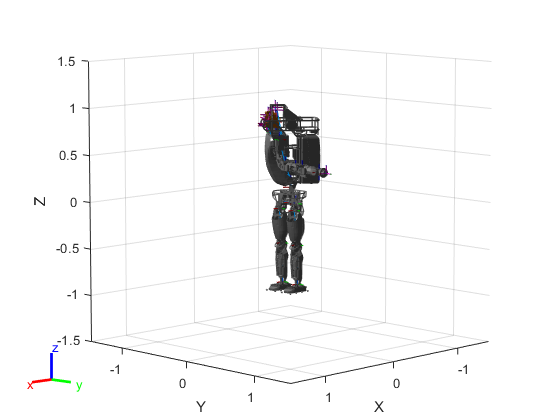

f = figure;
ax = axes(f);
for t = 1:30:size(qTraj,2)
    show(atlas, qTraj(:,t), "Parent", ax, "PreservePlot", false, "FastUpdate", true);
    pause(0.01);
    drawnow;
end